# MXB201 Exercises 5

T1.  Let the SVD of $A$ be $A = U\Sigma V^T.$  What is the SVD of (a) $2A$; (b) $A^T$; (c) $A^{-1}$, assuming $A$ is invertible.

T2.  Explain why the SVD is not a helpful tool for calculating matrix powers, or matrix functions.

T3.  Let $W \in \mathbb{R}^{n \times 1}$ be a matrix with a single column.  What is the reduced SVD of $W$?  What is the pseudoinverse $W^+$?

T4.  A property we have used frequently for invertible matrices is $(AB)^{-1} = B^{-1} A^{-1}$.  For general matrices (rectangular, square, invertible or not) we can define the pseudoinverses $A^+$ and $B^+$ using the SVD.  Prove, or find a counterexample to disprove, that $(AB)^+ = B^+ A^+$ in general.

**See PDF of written solutions.**

## Practice  

P1.

Let $A$ be defined by

A = ([
     1     3     3
     1    -1    -1
     2     2     2
     3     5     5
     5     3     3])

A =      1     3     3
     1    -1    -1
     2     2     2
     3     5     5
     5     3     3


(a) Use MATLAB to calculate the (reduced) SVD of $A$.

[U,Sigma,V] = svd(A,'econ')

U =    -0.3705   -0.4128    0.0498
    0.0631    0.5024    0.8316
   -0.3075    0.0896   -0.0125
   -0.6780   -0.3232    0.3816
   -0.5518    0.6817   -0.4002


Sigma =    11.2296         0         0
         0    3.1459         0
         0         0    0.0000


V =    -0.5090    0.8608         0
   -0.6087   -0.3599   -0.7071
   -0.6087   -0.3599    0.7071


(b) Explain why this SVD reveals that $A$ has rank 2.  Hence write $A$ as the sum of 2 rank-1 matrices.

A2 = U(:, 1:2) * Sigma(1:2, 1:2) * V(:, 1:2)'

A2 =     1.0000    3.0000    3.0000
    1.0000   -1.0000   -1.0000
    2.0000    2.0000    2.0000
    3.0000    5.0000    5.0000
    5.0000    3.0000    3.0000


T1 = Sigma(1,1) * U(:, 1) * V(:, 1)'

T1 =     2.1178    2.5326    2.5326
   -0.3605   -0.4312   -0.4312
    1.7573    2.1015    2.1015
    3.8751    4.6341    4.6341
    3.1540    3.7718    3.7718


T2 = Sigma(2,2) * U(:, 2) * V(:, 2)'

T2 =    -1.1178    0.4674    0.4674
    1.3605   -0.5688   -0.5688
    0.2427   -0.1015   -0.1015
   -0.8751    0.3659    0.3659
    1.8460   -0.7718   -0.7718


rank(T1), rank(T2)

ans = 1

ans = 1

norm(T1 + T2 - A)

ans = 2.3783e-15

(c) What is the best rank-1 approximation of $A$?

T1, A

T1 =     2.1178    2.5326    2.5326
   -0.3605   -0.4312   -0.4312
    1.7573    2.1015    2.1015
    3.8751    4.6341    4.6341
    3.1540    3.7718    3.7718


A =      1     3     3
     1    -1    -1
     2     2     2
     3     5     5
     5     3     3


(d) Use this SVD to obtain orthonormal bases for the row space, column space and null space of $A$.

U, V, Sigma

U =    -0.3705   -0.4128    0.0498
    0.0631    0.5024    0.8316
   -0.3075    0.0896   -0.0125
   -0.6780   -0.3232    0.3816
   -0.5518    0.6817   -0.4002


V =    -0.5090    0.8608         0
   -0.6087   -0.3599   -0.7071
   -0.6087   -0.3599    0.7071


Sigma =    11.2296         0         0
         0    3.1459         0
         0         0    0.0000


RS = V(:, 1:2)

RS =    -0.5090    0.8608
   -0.6087   -0.3599
   -0.6087   -0.3599


CS = U(:, 1:2)

CS =    -0.3705   -0.4128
    0.0631    0.5024
   -0.3075    0.0896
   -0.6780   -0.3232
   -0.5518    0.6817


NS = V(:, 3)

NS =          0
   -0.7071
    0.7071


null(A)

ans =          0
   -0.7071
    0.7071


orth(A), orth(A')

ans =    -0.3705   -0.4128
    0.0631    0.5024
   -0.3075    0.0896
   -0.6780   -0.3232
   -0.5518    0.6817


ans =    -0.5090    0.8608
   -0.6087   -0.3599
   -0.6087   -0.3599


(e)  Use this SVD to calculate the pseudoinverse $A^+$.  Compare it to MATLAB's `pinv(A)`.

pinvA = V(:, 1:2) * diag(1./diag(Sigma(1:2,1:2))) * U(:, 1:2)'

pinvA =    -0.0962    0.1346    0.0385   -0.0577    0.2115
    0.0673   -0.0609    0.0064    0.0737   -0.0481
    0.0673   -0.0609    0.0064    0.0737   -0.0481


pinv(A)

ans =    -0.0962    0.1346    0.0385   -0.0577    0.2115
    0.0673   -0.0609    0.0064    0.0737   -0.0481
    0.0673   -0.0609    0.0064    0.0737   -0.0481


(f) Use the pseudoinverse $A^+$ to find the minimal norm solution $x = \textrm{argmin}_{x^* \in \mathbb{R}^n} \|b - Ax^*\|$ where $b = [1,2,3,4,5]^T$.

b = (1:5)';
xplus = pinvA * b

xplus =     1.1154
    0.0192
    0.0192


norm(b - A*xplus)

ans = 1.4412

x2 = A \ b

x2 =     1.1154
    0.0385
         0


norm(b - A*x2)

ans = 1.4412

norm(x2), norm(xplus)

ans = 1.1160

ans = 1.1157

Confirm the solution lies in the row space of $A$.

NS' * xplus

ans = 1.7347e-18

P_RS = RS * RS'

P_RS =     1.0000    0.0000    0.0000
    0.0000    0.5000    0.5000
    0.0000    0.5000    0.5000


P_RS * xplus, xplus

ans =     1.1154
    0.0192
    0.0192


xplus =     1.1154
    0.0192
    0.0192


## Exploration

E1.

Download a colour image from the internet (if you liked the waterfall picture from the lecture, it's [here](https://unsplash.com/photos/DBGb9u1Yf6Q/), but you might prefer a lower resolution version for this question).

Experiment with using the SVD for image compression.

(a) Calculate SVDs of the red, green and blue channels separately

(b) Convert to HSV colour space (see `rgb2hsv` and `hsv2rgb` commands`)`, and calculate SVDs of the hue, saturation and value channels separately

(c) Stack the red, green and blue channels on top of one another, and compute one giant SVD

(d) Stack the hue, saturation and value channels on top of one another, and compute one giant SVD

Which of the options seems to work best?  Can you be quantitative with your answer?

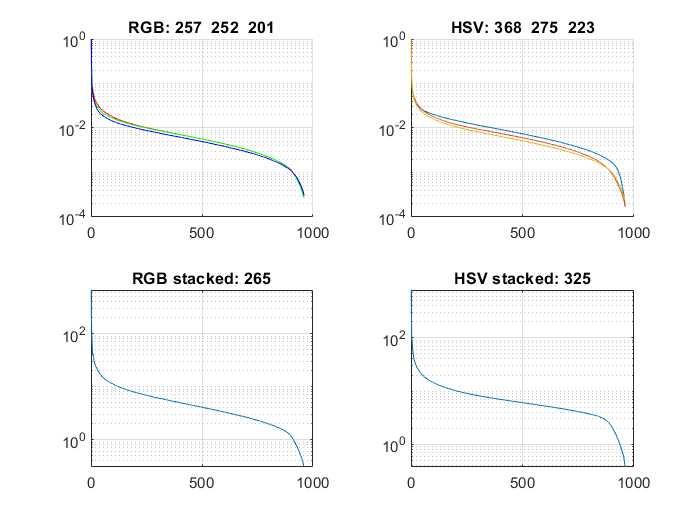

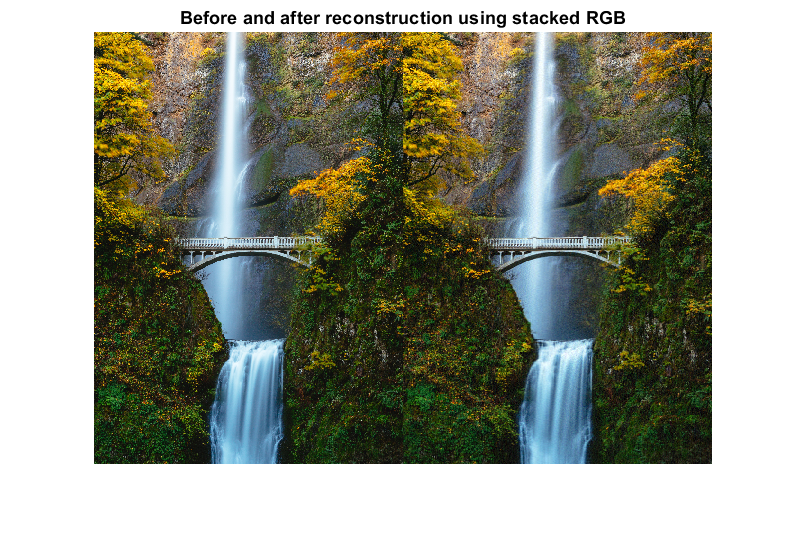

waterfall_compression

**The stacked RGB approach works the best, requiring only 265 pairs of singular vectors to reconstruct to within 1%.  The final image looks indistinguishable.**